# 7. Transistor Switches

© B. Rasnow 01Jun25

## Objectives 

Measure and understand the behaviors of bipolar junction transistor (BJT) and field effect transistor (FET) switches. Design and prototype an LED nightlight that switches on in the dark and off in the light.

## Methods 

Look up transistor datasheets on the Internet, in particular to determine the pinouts of your devices. 

### Hardware interfaces

  (a)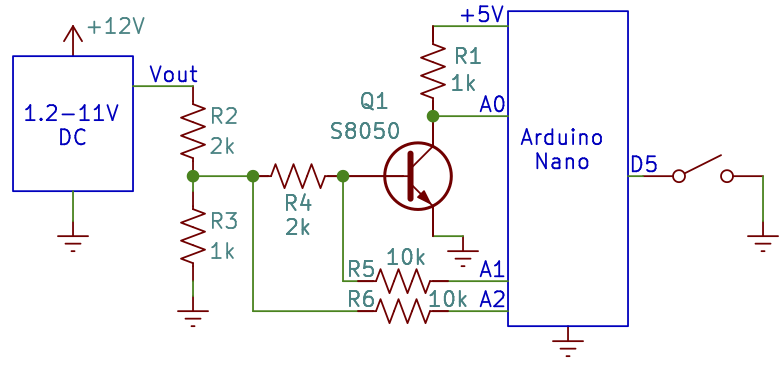(b)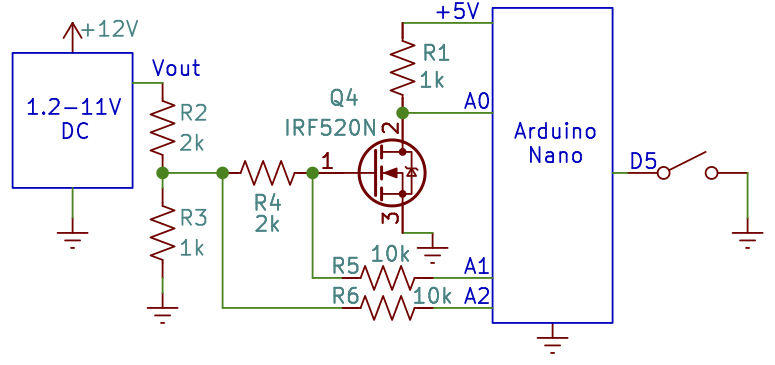

(c)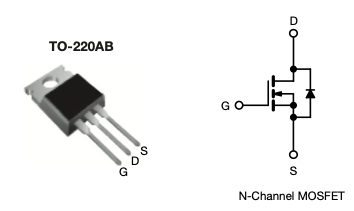

    Figure 1. (a) Test circuit for a transistor switch, with an NPN BJT (e.g., S8050 or 2N2222). Note the base resistor R4 is  much smaller than in the previous chapter, otherwise the circuit is the same. (b) Similar circuit for an N-channel MOSFET (e.g., IRF520), with gate, drain, source = base, collector, emitter respectively.  (c) Pinout for an IRF520 or IRFZ44N.

**Adding an LED in series with R1** provides a qualitative visual indicator of the state of the switch, that can be useful initially to verify that varying the LM317 voltage turns the transistor on and off. Don't forget to **remove the LED before measuring voltages** with a the Arduino. 

Powering the collector side of the transistor from Arduino's 5V achieves 3 things: 1) it provides a constant voltage, so only the base voltage (and current) are varied and changes in the collector are "dependent" variables;  2) that voltage *is* 1023ADU = vref, so we don't need to measure it every time; and 3) the collector voltage can be safely measured without a voltage divider and risk of overvoltage to the Arduino. Because the Arduino's 5V power supply can't supply much current, ensure R1 > $500\Omega$.

The base voltage is applied through a voltage divider, R2 and R3. We previously used that divider to measure Vin from the power supply, but here we're also connecting the divided voltage because we expect the BJT's switching behavior to begin ~0.5V, below the minimum output of the LM317, but above the divided voltage, ~1.25V/3. We've also reduced the base resistor from our beta experiment, so 100 times more base current flows for a given input voltage, and the transistor will saturate at a lower input voltage. This is the key feature of a switch circuit. Whereas the previously large R4 = 1M "spread out" the active region of the BJT over a wide range of Vin, the goal of a switching circuit is to compress that range so the transition from "off" to "on" (saturated) occurs rapidly.

R5 and R6 provide extra protection to the Arduino just in case the ground on R3 were disconnected. In that case, R2 would provide adequate current limiting, but I'm just in the habit of keeping 10k resistors in series with analog inputs as a general rule, and have them soldered to the white jumper wires (Fig. 2).

  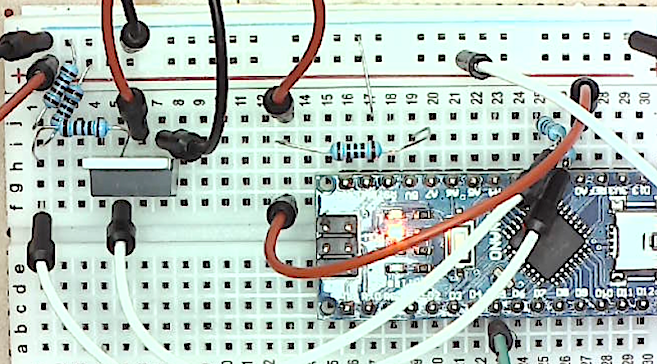

Figure 2. Breadboard implementation of Fig. 1 with an IRFZ44N MOSFET. 

### Software interface

Identical to the code for measuring beta in the prior chapter. 

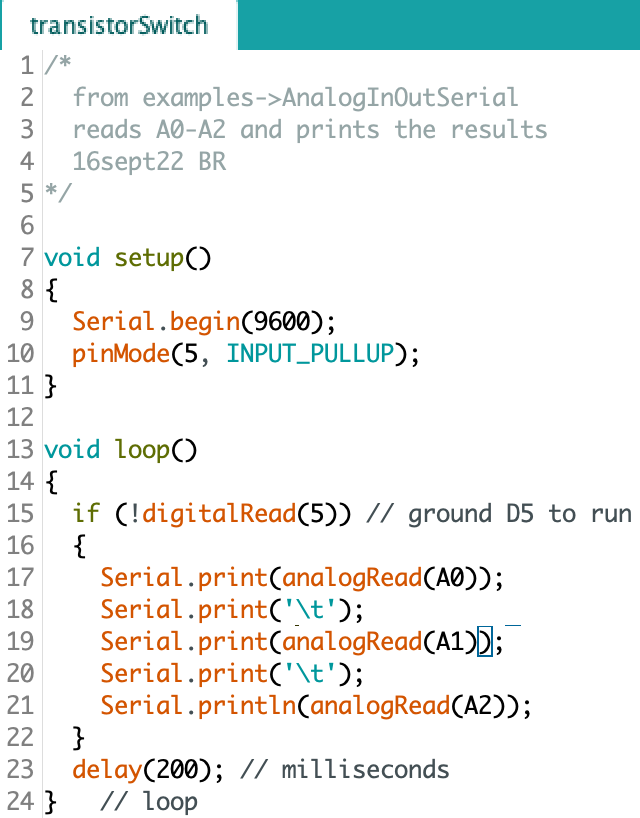

Figure 3. Arduino source code.

### Data interface 

The source code in Results describes the "unpacking" of the 3 columns of voltage data and calculation of base current through R4. Trial-and-error ([exploratory data analysis, EDA](https://en.wikipedia.org/wiki/Exploratory_data_analysis)) resulted in some parameters, such as multipliying `ib` by 1e3 and `ig` by 1e6 to scale with the other variables on the plot.  

## BJT Results

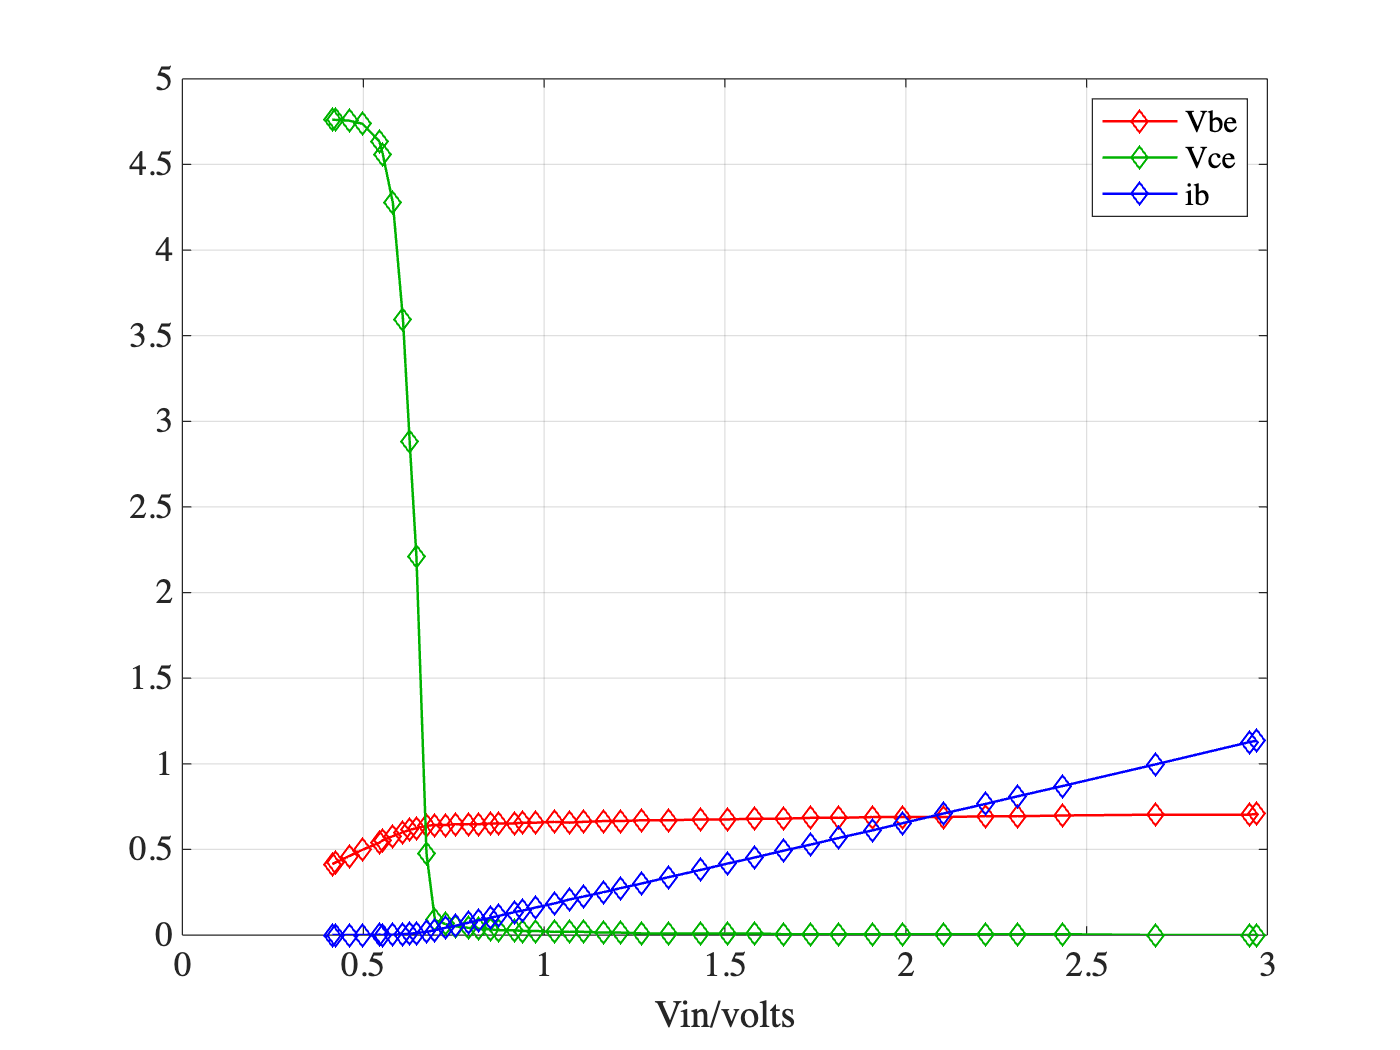

vref = 4.76; % volts
Rb = 1.995e3; % base resistor, R4, ohms
Rc = 999; % collector resistor, R1, ohms
data = [... % A0-A3
1023	89	89
1023	91	91
1022	99	99
1018	107	107
996	116	117
980	119	119
919	124	125
773	129	131
619	132	135
475	134	139
102	137	145
19	138	150
14	138	156
11	139	162
9	139	170
8	139	176
7	140	183
6	140	188
6	140	197
5	141	202
5	141	210
4	142	221
4	141	230
4	142	238
3	143	250
3	143	260
2	144	273
2	144	289
2	145	308
2	145	324
2	146	340
1	146	357
1	147	373
1	147	390
1	148	410
1	148	428
1	148	452
1	149	477
1	149	496
1	150	523
0	151	578
0	151	634
0	152	638] * vref / 1023; % now in volts
vce = data(:,1); % collector-emitter voltage
vbe = data(:,2); % base-emitter voltage
vin = data(:,3);
ib = (vin-vbe)/Rb * 1000; % base current in mA
plot(vin, [vbe vce ib],'.-')
grid; xlabel('Vin/volts'); 
legend('Vbe','Vce','ib')

Figure 4. Measured base-emitter and collector-emitter voltages and base current (times 10, in mA).

## BJT Discussion

There's a lot to unpack here. Not in any particular order: 

- $V_{BE}$ rises (~linearly) with Vin <~0.7V and then stays constant, not exceeding 

max(vbe)

ans = 0.7073

- $V_{CE}$ started at Vref, but when $V_{BE}$ > 0.5V, it fell off a steep cliff towards zero. 

- $i_B$ is around zero for Vin <~ 0.6V (below the knee of the base-emitter diode) and rises linearly with Vin above the knee. When current rises linearly with voltage, the slope is 1/R, which we can estimate by eyeball: R = $\Delta x / \Delta y$ ~ 2$k\Omega$ = the base resistor R4. 

### An NPN switch is an Inverter or NOT gate

The collector voltage, $V_{CE}$, is in a Boolean sense the negation of the input, i.e., this switch is a NOT gate, with truth table: 

It's not "binary" in the sense that there is a continuous (analog) zone between 0.55V<Vin<0.7 where the collector has intermediate values. What makes a circuit like this approximately Boolean is the narrow transition zone, and the speed at which it can transition through that zone. All computer circuits are analog in this way, and what makes them "digital" is (drum roll) .... *a clock* that tells the system not to test or query the device's state until it has had time to transition and settle into a stable (Boolean) final state. 

### A transistor has power gain

Let's compute the power of the input (base) and output (collector) circuits, and display on both linear and semilog scales:

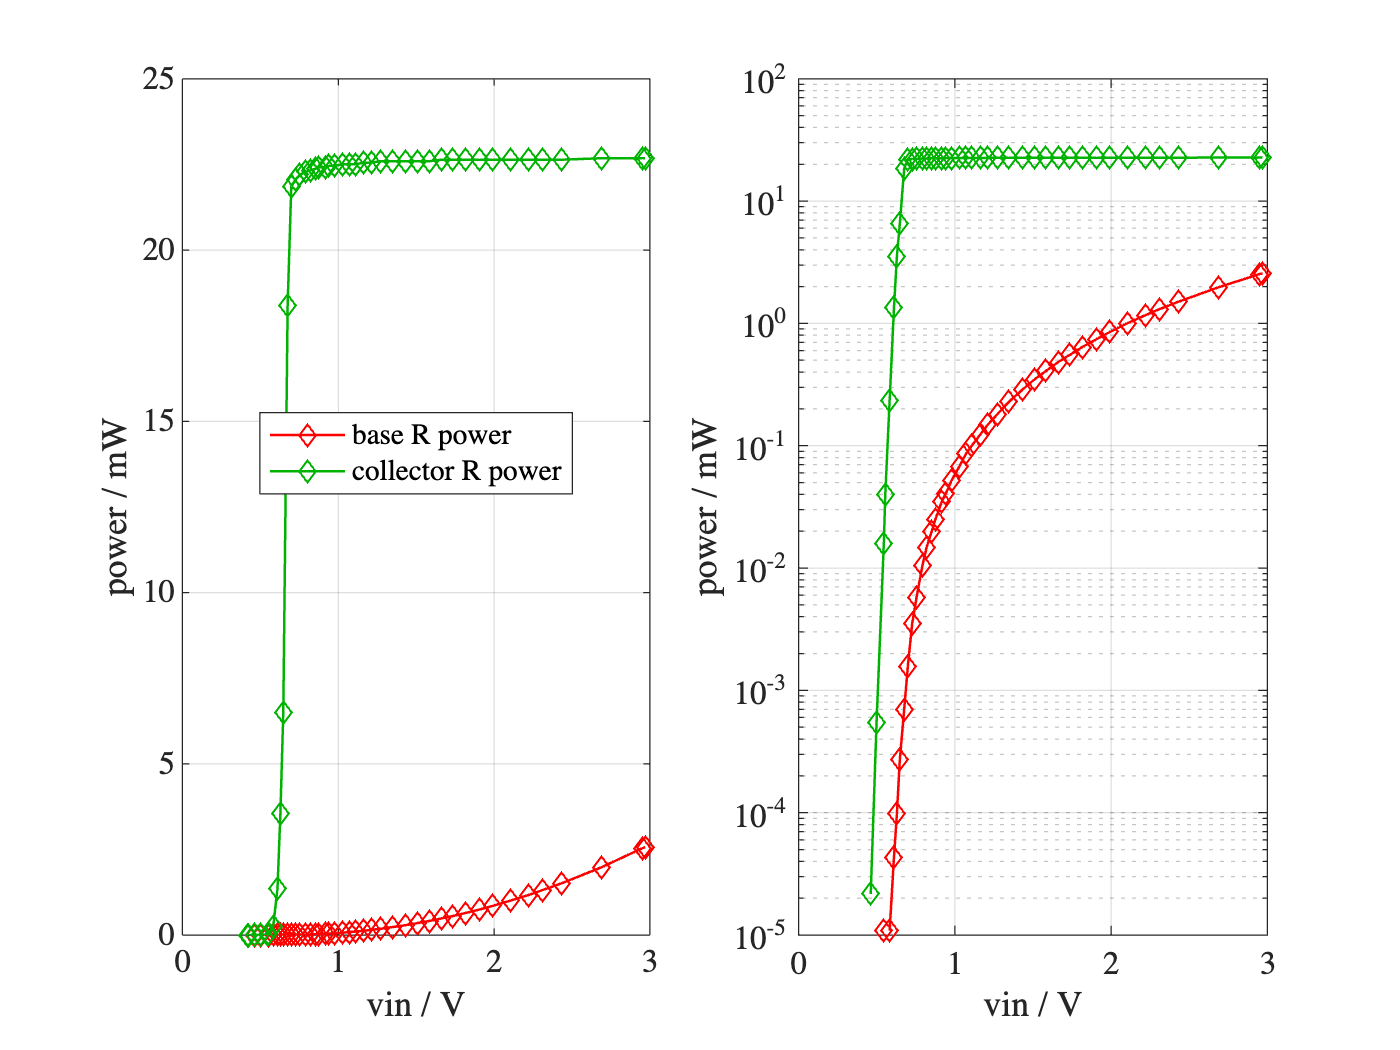

Prb = (ib/1e3).^2 * Rb; % watts
Prc = (vref-vce).^2 / Rc; % watts
subplot(1,2,1);
plot(vin, [Prb Prc]*1000, 'd-')
xlabel('vin / V'); ylabel('power / mW'); grid
legend('base R power','collector R power','location','best')
subplot(1,2,2); 
semilogy(vin, [Prb Prc]*1000, 'd-')
grid; 
xlabel('vin / V'); ylabel('power / mW');

Figure 5. Power by base and collector resistors vs. input voltage. 

A small base current controls a much larger collector current. The ratio of these curves is the power gain: 

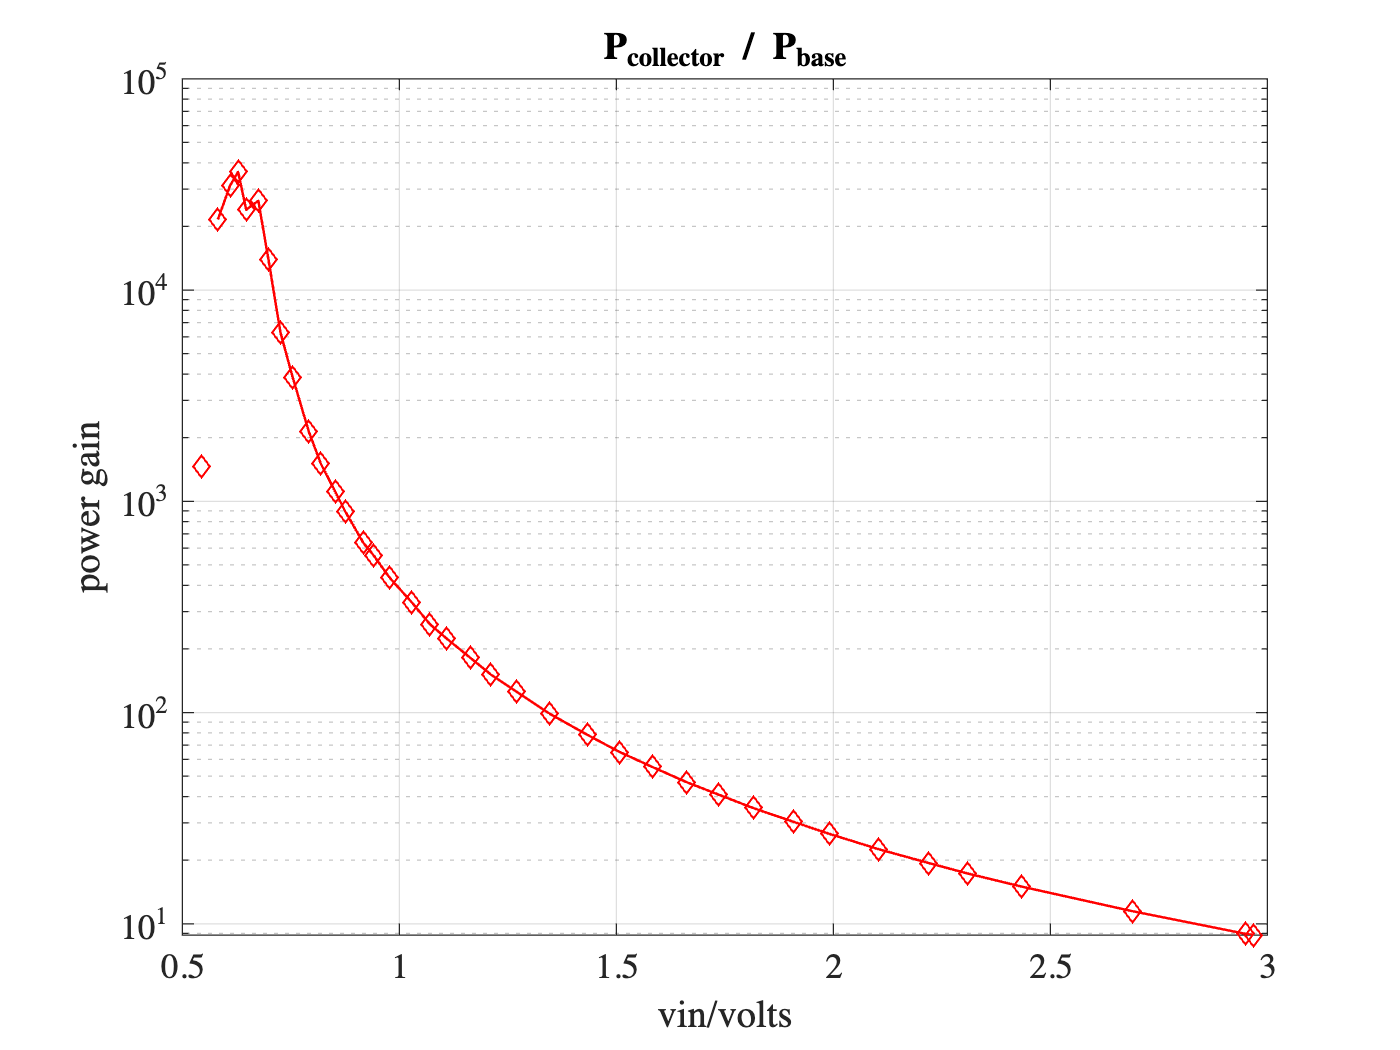

gain = Prc ./ Prb;
clf; % get out of subplot mode
semilogy(vin, gain, 'd-');
grid; xlabel('vin/volts'); ylabel('power gain')
title('P_{collector} / P_{base}')

        Figure 6. BJT power gain.

Power gain drops as vin >~.6V bceause once the transistor is turned fully on, the collector power is constant while the base power increases. Increasing base power often accelerates the transistor's switching speed.

### Voltage divider loading error

My power supply puts out max(V) ~ 10.7V, which the 2k$\Omega$+1k$\Omega$ voltage divider should reduce to

10.7 / 3 % volts

ans = 3.5667

But the x-axis (Vin) of all the graphs above ranges from ~0.5-2.9V. 2.9 $\ne$ 3.6, so how can we explain that error? 

The answer is a common phenomenon with voltage dividers. The load -- in this case the base resistor and base-emitter -- are "pulling down" the voltage by drawing current. Here's how: 

   (a) (b) 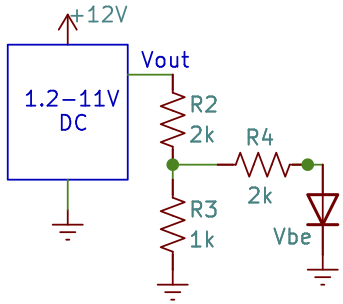

Figure 7. (a) Fig. 1, and (b) equivalent circuit showing approximate loading of the voltage divider. 

The voltage divider equation we used only considered R2 and R3, but there are other current paths from the node between those two resistors. The lower right one in the schematic goes to A2 of the Arduino, but that's a high impedance (see References below), so no significant current flows. The upper path does draw current, and we already measured how much: max(ib) = 1.14mA (Fig.4, blue, is mA; Note we're ignoring the path to A1 for the same reason as A2). That seems like a little, but everything is relative. The total current through R2 (ignoring the parallel paths for the moment) would be 10.7V/(R2+R3) ~4mA -- so about 25% of R2's current could be hijacked through R4 instead of R3 -- which will affect the voltage divider. The base-emitter acts like a forward biased diode with Vf ~ constant 0.6V. Vbe $\sim$0.6V $\sim$ 0V when Q1 is on, so R2 is in series with approximately R3 || R4 = 667$\Omega$, producing a maximum voltage ~ 10.7*667/(667+2k)  = 

10.7*667/(667+2e3)

ans = 2.6760

That's less than we measured, and qualitatively, you should convince yourself that adding .6V to the bottom of R4 should push the voltage divider upwards, towards the voltage that we measured. With a little more effort you could solve this circuit more accurately.

## FET Results

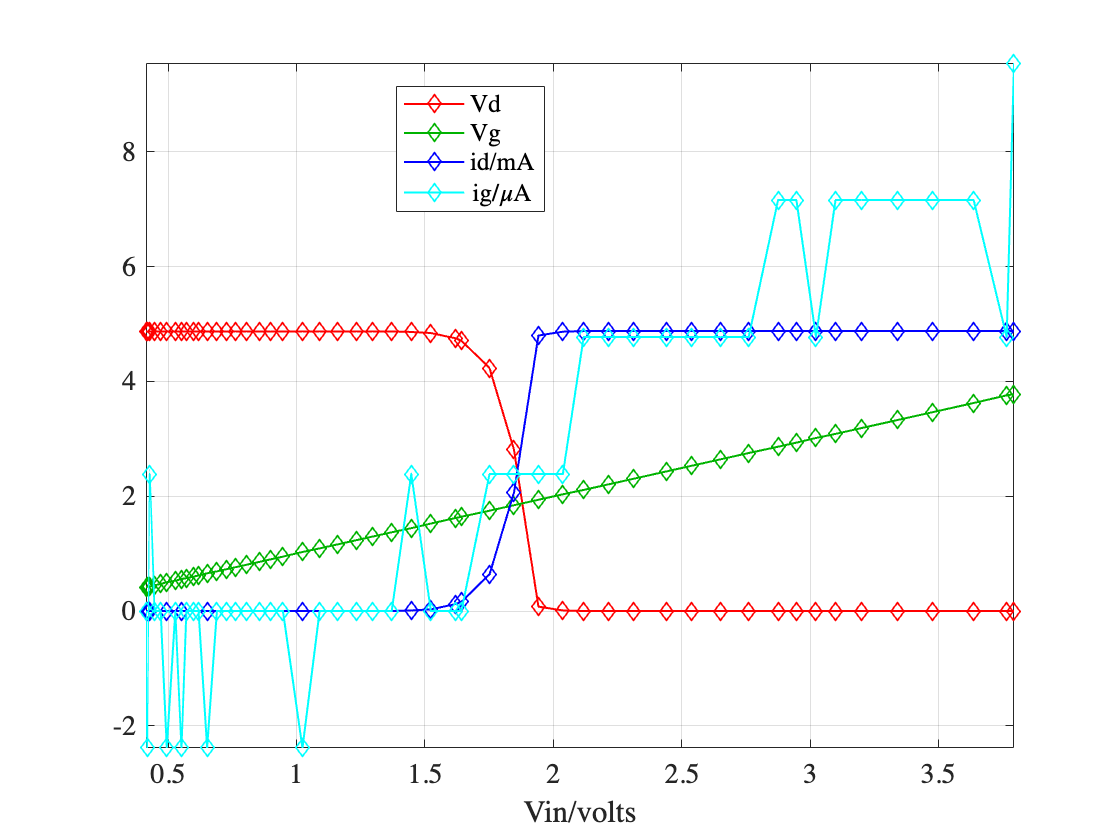

vref = 4.87;
Rg = 1.995e3; % gate resistor, R4, ohms
Rd = 999; % drain resistor, R1, ohms
data = [ ... % A0 A1 A2
1023	87	87
1023	89	88
1023	89	90
1023	94	94
1023	99	99
1023	105	104
1023	111	111
1023	111	111
1023	117	116
1023	120	120
1023	126	126
1023	130	130
1023	138	137
1023	145	145
1023	153	153
1023	160	160
1023	169	169
1023	180	180
1023	189	189
1023	199	199
1023	216	215
1023	229	229
1023	244	244
1023	259	259
1023	272	272
1023	288	288
1021	303	304
1017	320	320
998	340	340
989	345	345
889	367	368
590	387	388
16	407	408
2	427	428
0	443	445
0	463	465
0	484	486
0	511	513
0	531	533
0	555	557
0	578	580
0	601	604
0	616	619
0	633	635
0	648	651
0	669	672
0	699	702
0	727	730
0	761	764
0	789	791
0	793	797
] * vref / 1023;
vd = data(:,1); % drain voltage
vg = data(:,2); % gate voltage
vin = data(:,3);
ig = (vin-vg)/Rg * 1e6; % gate current, uA
id = (vref-vd)/Rd * 1e3; % drain current, mA
clf;
plot(vin, [vd vg id ig],'d-')
xlabel('Vin/volts'); grid; 
legend('Vd','Vg','id/mA', 'ig/\muA','location','best');
axis tight;

   Figure 8. FET switching characteristics. Note gate current is multiplied by 1000 vs. drain current, and $\sim 2\mu A$ = 1 ADU is the gate current resolution.

Trial was repeated a couple of times and the plots overlapped. 

## FET Discussion

### Threshold

The bimodal switch behavior seen on the drain: off for Vin < ~1.7V and on for Vin > 2.1V, is similar to the BJT. The gate threshold is much higher -- ~2V for this MOSFET, vs. ~.7V for the BJT's base. Page 2 of the datasheet has a parameter "Gate-source threshold voltage" specified between 2.0-4.0V, is consistent with what was measured. The tiny integrated FETs in CPUs tend to have much lower thresholds, some <1V, reducing power and heat generation. 

### Gate Current

There isn't much gate current, $-2\mu A <\sim i_g <\sim 8\mu A$ for 0.5<Vin<3.7V. The discrete ADU units are apparent in the data: ~2$\mu A$ * 2k$\Omega$ = 4mV * 1023ADU/5V ~ 1 ADU. Why is the left half of the curve *negative*? Is current flowing *out of *the gate!? More likely, this 1 ADU error has other causes we'll explore later. We can estimate a resistance corresponding to the right side of this curve: $\Delta y/\Delta x$ ~ 7e-6A/(3.5-1)V ~ $360K\Omega$, much higher than any resistance we put in the circuit, so this must be *intrinsic* to the gate. But again, this result is based on just 3 ADU difference so it only is credible to <1 significant figure. The gate current could actually be orders of magnitude smaller, the gate resistance many orders of magnitude greater (e.g., >1e10$\Omega$). So this is opposite of BJTs, who's base resistance is close to $0\Omega$ once the transistor is on (Vbe>0.6V, and the base-emitter diode is in the vertical (~exponential) regime of its hockey-stick i-v curve). 

A consequence of high gate resistance/low gate current is that the x-axis extends the full range of our voltage divider: 

[10.7*R3/(R2+R3) max(vg)]

The voltage divider loading of Fig. 7 is absent, with the gate impedance >> $R_{Thevenin}$ of the voltage divider. 

### Drain current vs. gate voltage

Since Vin (x-axis of Fig. 8) is not a "characteristic" of the device, it is more useful to plot drain current vs. gate voltage, as we did for gate current. We'll do it on linear and semilog axes: 

subplot(1,2,1); 

ans =     3.6432    3.7751


plot(vg, id, 'd-');
grid; xlabel('gate voltage/volts'); ylabel('drain current/mA')
subplot(1,2,2); 
semilogy(vg, id, 'd-');
grid; xlabel('gate voltage/volts'); ylabel('drain current/mA')

        Figure 9. Drain current.

The lowest value, `min(id) = 0`, aren't on the log plot. The `semilog` plot's transition is very linear, suggesting drain current does increase exponentially with increasing gate voltage until saturation. When linear responses are desired (from FETs or BJTs), this is achieved using negative feedback.

### Plateau

For Vg > 2.1V, the drain current reaches a plateau around 

max(id)

So what determines this current? Once the FET is fully turned on, it's resistance between drain and source, $R_{DS(on)} < 0.017\Omega$ according to the datasheet -- effectively zero, so the drain current should be: 

vref / Rd * 1000 % mA

Impressive agreement!? 

## Applications

### Switching relays, solenoids, and SSRs

Relays and solenoids are electromechanical transducers that can exert strong mechanical forces via magnetic fields in their core. Electrically, their coils have low resistance (hence require high currents) and high inductance, $L$, a consequence being that they generate (positive *or* negative) voltages in response to sudden changes in current:  $V = L\frac{dI}{dt}$. Hence interfacing to relays and solenoids poses two challenges: 1) provide enough current to activate the solenoid, and 2) protect sensitive circuitry from their inductive "kickback" voltages when they switch state. 

[**Snubber circuits**](https://en.wikipedia.org/wiki/Snubber) filter or attenuate these inductive voltages. A reverse biased diode in parallel with the load (D1 in Fig. 10) can effectively snub the negative voltages. Normally its impedance is high, but $\approx 10^{-11}$ seconds after $-V < -V_f \approx -.7V$, the diode conducts, i.e., its resistance $R \rightarrow 0$ and $L\frac{dI}{dt} = I(R_{inductor} || R_{diode})$ is "snubbed". Replacing D1 with a zener diode D2 will not only conduct negative transients but also conduct during positive transients when $V>V_{Zener}$. Often a second zener, D3 is manufactured in series with D2 providing bidirectional clipping for $|V| > V_{Zener}$, these are called **transient voltage suppression diodes. **When one diode is in zener breakdown, the other is forward biased and just adds $V_f \approx 0.7V$ to the circuit. An RC snubber is robust and inexpensive. We'll analyze capacitive circuits soon, but key is that C's respond to changes in voltage with proportional currents, $I = C \frac{dV}{dt}$ that the (small) series resistor dissipates as $IR$. While the inductor is either on or off, $V \approx$ constant and the snubber current is zero, it's "not there".  More snubber circuits are described in this tech note: [https://www.ti.com/seclit/an/slup100/slup100.pdf.](https://www.ti.com/seclit/an/slup100/slup100.pdf.) 

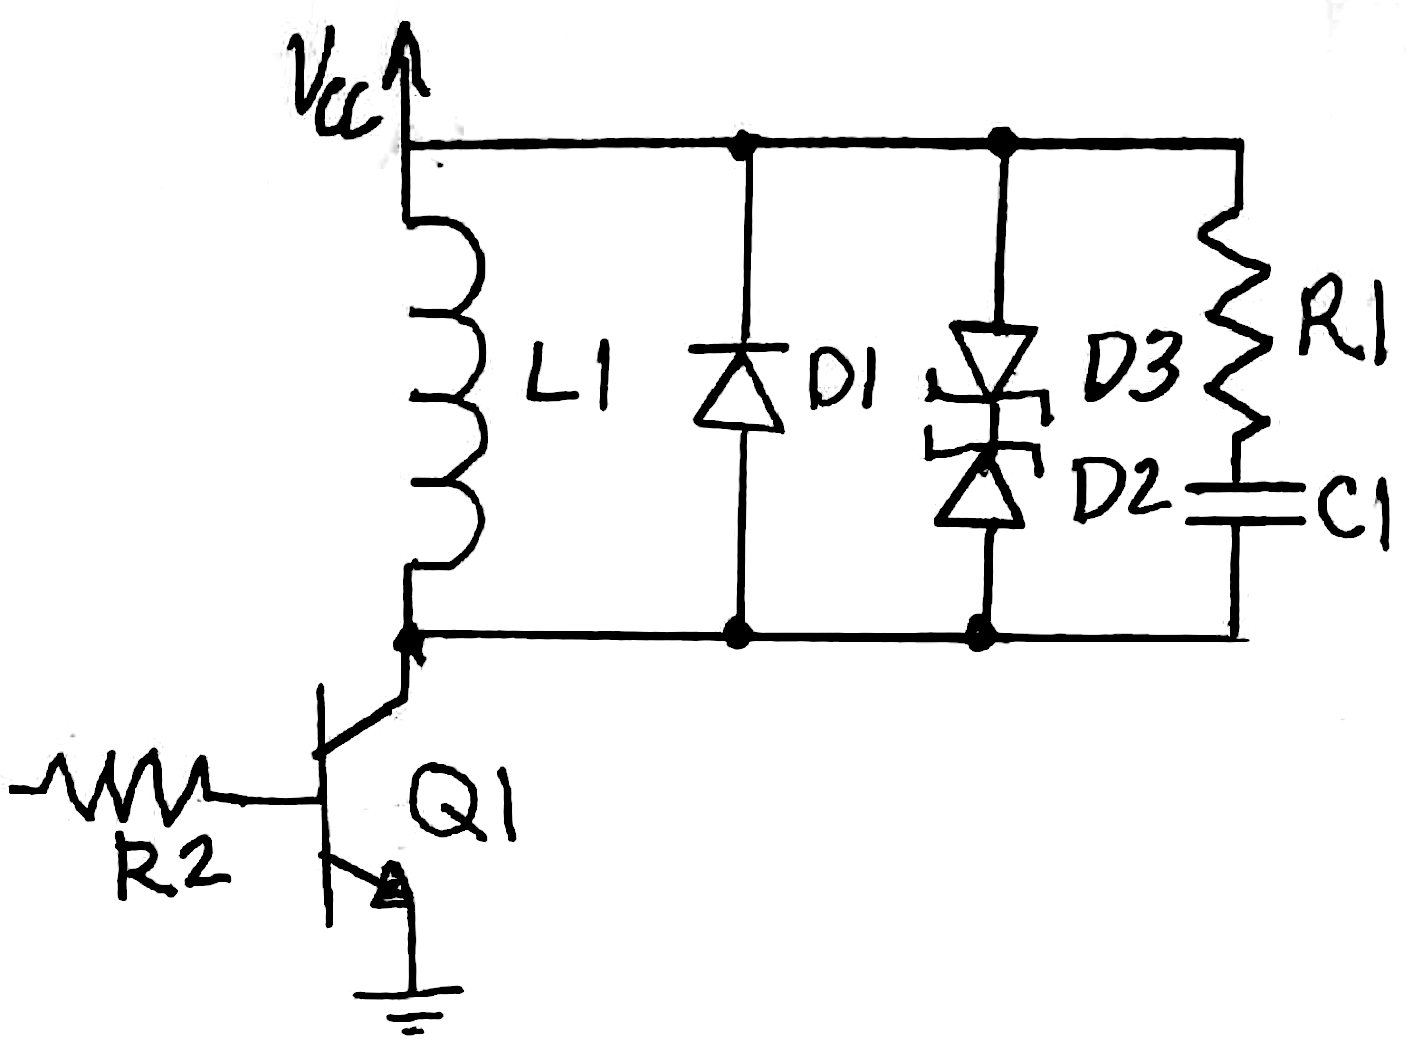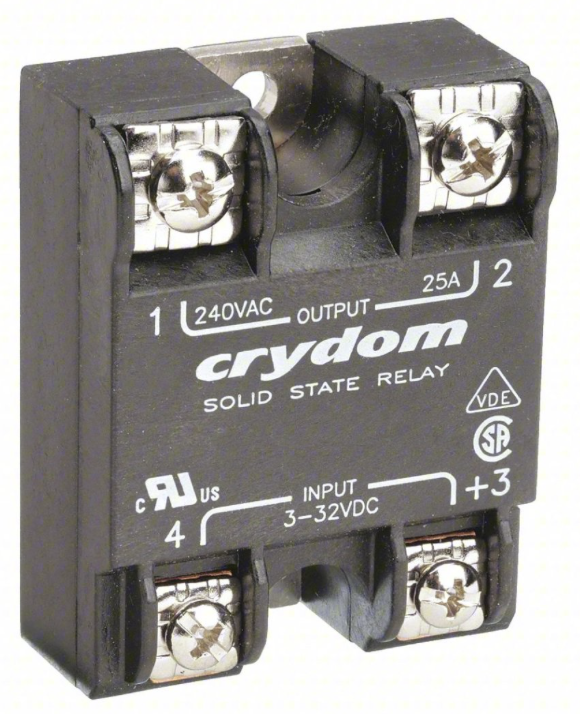

        Figure 10. Three snubber circuits shown in parallel with a switched solenoid or relay coil, L1. Open collector switch Q1 enables microcontrollers to switch large currents through L1 and also isolates the base of Q1 from Vcc. Solid state relays (right) switch even larger loads.

Providing adequate solenoid current (and power) often requires a high voltage. E.g., controlling a 12V, 1A (12W) solenoid from a microcontroller digital output capable of sourcing <20mA at 5V (<100mW) requires power gain >120. 

NPN **open-collector switches** (Q1 in Fig. 10) can be a robust solution. As long as $i_{load} \le \beta i_{base}$, by switching current near ground, they aren't affected by high load voltages (within their limits, see datasheets). If fast ($<10^{-6}$ second) switching times aren't needed, a **Darlington** **transistor** can replace Q1. n-channel **MOSFET's**, with nearly infinite input impedance and very low output impedance are best for high loads. Many have various internal snubber circuits integrated inside them (e.g., the diode in Fig. 1C). For large inductive loads, such as 240VAC motors and pumps, **solid state relays **(SSR, Fig. 10) are ideal. These are usually potted (blocks of epoxy) containing one or more switched MOSFET circuits (no physical relays are inside), LED indicators, and snubbers, everything necessary to interface a microcontroller with large powerline connected loads. Some SSRs implement time delays to switch the load at the AC voltage's zero crossing, in order to reduce inductive power. SSRs have made mechanical relays obsolete in most applications. 

### CdS Controlled LED nightlight

Let's put our switch knowledge to work by building an LED nightlight that switches on in the dark and off in the light. Insert an LED in series with R1 and verify the LED switches on and off via changes in base current or gate voltage. Your kit contains a cadmium sulfide (CdS) photoresistor ([https://en.wikipedia.org/wiki/Photoresistor](https://en.wikipedia.org/wiki/Photoresistor)), who's resistance varies with ambient illumination. 

- Characterize the CdS resistor by measuring its resistance (with your DMM multimeter on resistance scale) in dark and light. Covering it with your finger should change its resistance. Try other opaque material too -- like a pen cap. Does your finger transmits some infrared (IR) light that the CdS sensor is sensitive to? [Fun fact: why is blood red? Because it absorbs green and blue light, but transmits red light].

- Choose a resistance value, $R_{Thresh}$ corresponding to the illumination where you want the LED to turn on.

- Design a switch using the CdS resistor and a transistor, and your LM317 set to 10V. No need to connect the Arduino -- for simplicity and safety to the Arduino, just use your DVM for measurements. 

- Prototype the circuit, demonstrate it works, and measure its performance (i.e., relevant voltages and currents.)

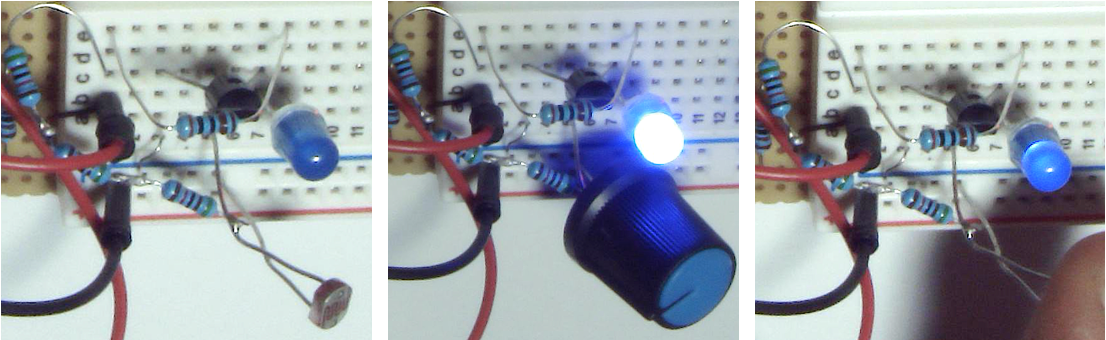

        Figure 11. A BJT switch powered with 10V, LED is off in the light (left), brightly on when the CdS resistor is covered with a knob (middle), and barely glowing with a finger over it (right). 

Hint: Use the CdS resistor as part of a voltage divider on the transistor base or gate. Compute the value of the other voltage divider resistor such that the divided voltage on the base or gate at $R_{Thresh}$ = the transistor threshold.

**Assessment: **Draw your CdS circuit and explain its theory of operation.

## Conclusions

Fig. 4 and Fig. 8 show the switching characteristics of a BJT (and FET) happen over a narrow range of base (gate) voltage and current, and their steep transitions make transistors amenable for digital circuits that represent two Boolean states. The different solid state physics of these devices are evident in their different threshold voltages and currents. BJTs use base current to control larger collector currents whereas the FET has almost no (DC) gate current but requires a larger gate voltage to activate and saturate its drain current. The BJT's base has low resistance when biased above it's ~0.6V knee, whereas the FET's gate has huge DC resistance. We saw a consequence of the BJT's low base impedance was it loaded the voltage divider supplying it, reminding us why we built an LM317 was to achieve a power supply with high efficiency and low $R_{Thevenin}$ that wasn't susceptible to loading like voltage dividers are. 

Power gain can be enormous because P = $V^2/R = i^2R$, so a voltage or current change of 1000 results in a power change of 1 million. I didn't compute power gain for the FET because gate power ~0, so gain ~ $\infty$. What was the maximum power gain for the BJT?

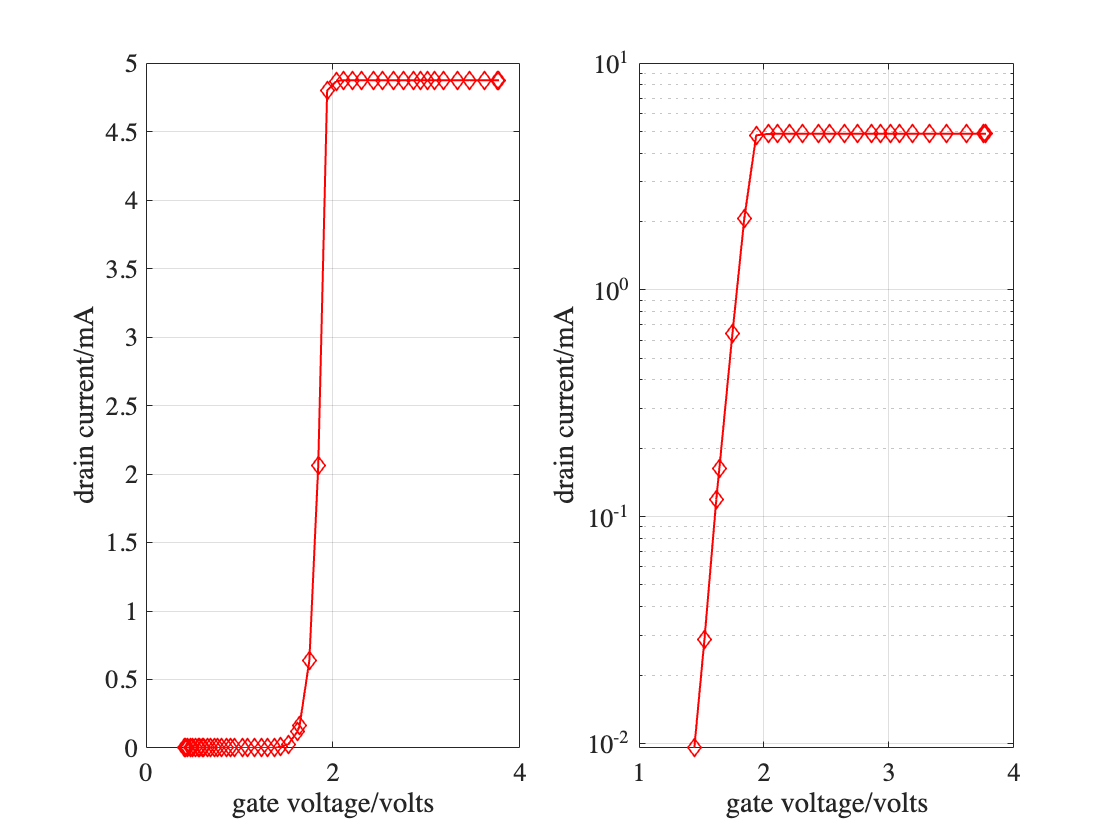

ans = 4.8749

ans = 4.8749

ans = 3.4530e+04

max(gain)

Surprised? Bug? No. The first data point, `vbe(1) = .42` V, is below the knee, and the measured base current `ib(1) = 0`, so divide by zero. Logarithmic plots in MATLAB don't show 0 (= $10^{-\infty}$). The 3rd data point had peak power corresponding to a beta = `sqrt(gain(3)) = 464`, which is high but plausible according to the data sheet. 

How might we explain the negative gate current of Fig. 8? I showed above that its amplitude was just a few ADU and thus close to a "noise floor". But all of the first 11 data points are negative, with a clear increasing trend. That systematic behavior rejects a noise hypothesis. Gate current wasn't directly measured but was computed by subtracting two measurements, `ig = (vin-vg)/Rg;`. `vin` and `vg` aren't measured simultaneously, but sequentially by Arduino, so small changes might occur between these measurements ("temporal skewing"). Turning the pot the other direction (from low to high vs. high to low) would change the sign if this were the cause. A1 and A2 might have slightly different gains inside the Arduino. This should be tested by applying the same voltage to both inputs. A much better way to measure small signals is "differentially", e.g., connecting a voltmeter lead to either side of Rg. 

This is our second experiment using an Arduino to measure voltage data and MATLAB to reduce the data into significant results and graphs. As before, we reduced the Methods into 3 blocks: hardware, software, and data interfaces, and we'll repeat that pattern in the future. Automating data acquisition and analysis makes collecting lots of data points almost effortless. It also lets us efficiently repeat the experiment numerous times until we're satisfied that the results are robust and correct, and all significant bugs have been eliminated. In developing this activity, I measured thousands of data points with lots of variants of the hardware and software, which would have been impractical without automation. 

Imagine doing this lab without Arduino and MATLAB. You'd use a large multi-output power supply with one output driving the collector of Fig. 1, and another varying the base current through R4. You'd move your DMM voltmeter leads sequentially from point to point measuring Vb, VR4 $\rightarrow$ ib = VR4/R4, and VR1 $\rightarrow$ ic = VR1/R1. Change the base voltage and repeat. You certainly couldn't measure 5 triplets of data per second, nor transcribe the DMM readings to a spreadsheet or calculator that quickly or accurately. Even simple computers like an Arduino crush our best abilities to measure and record data, so we can't compete against them, but instead have to work with them (and program them to work for us). 

How does it *feel* to be using a computer this way, to assist you in data acquisition and reduction? To explore your data with MATLAB's extensive collection of statistical, graphical, and other tools? To use Live Scripts that mix text, code, images, graphs, and computed results in a single "live" document? Live Scripts are unique to MATLAB (introduced around 2017). A very long time ago we were amazed when word processors let us embed pictures among text! Computers are moving away from the paradigm of documents having a single "owner" or application that opens them. Check out [https://jupyter.org.](https://jupyter.org.) I'd be really interested if you can show me this activity in that framework. 

## Homework

- Write a lab report describing your experiments with BJT and FET switches. Use electronics language and transistor theory (i.e., resistance, current, voltage, gain, and specifically Vbe, Vce, ib, ic, hfe or beta, Vgs, and so on).

- Design, prototype, and characterize an LED nightlight that turns on in darkness and turns off in light. Describe the characteristics of your CdS photoresistor in your kit ([https://en.wikipedia.org/wiki/Photoresistor](https://en.wikipedia.org/wiki/Photoresistor)). Include pictures of your LED and circuit on and off states. 

- Design a switch with 2 inputs that only turns on if both inputs are low (i.e., a NAND gate).

- Design a switch with 2 inputs that's a NOR gate, i.e., low if either input is high.

- Conclude with a meta-reflection of what you learned. 

## References

- Googling “arduino analog input impedance”, I found a rich discussion at: [https://forum.arduino.cc/index.php?topic=65134.0](https://forum.arduino.cc/index.php?topic=65134.0)[[i]](about:blank<#_edn1%3E): “The ATmega328P datasheet has this info way in the back: Table 28-16 (page 328). The analog input resistance is claimed to be 100 Mohms. During an actual sample, the input resistance is temporarily a lot lower as the sampling capacitor is charged up ...

- IRF520 power MOSFET datasheet: [https://www.vishay.com/docs/91017/irf520.pdf](https://www.vishay.com/docs/91017/irf520.pdf) 